% Live Script

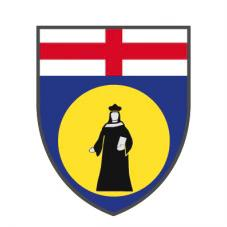

## **UNIVERSITA DEGLI STUDI DI GENOVA**

## **BIOMEDICAL FOR ROBOTICS**

## **Assignment 3 - Phantom Robot**

DIBRIS

DEPARTMENT OF COMPUTER SCIENCE AND

TECHNOLOGY, BIOENGINEERING, ROBOTICS

AND SYSTEM ENGINEERING

Authors

Davide Pisano, Miriam Anna Ruggero, Terrile Ivan

December 2023

## 1 - Reaching Task

#### *Introduzione: *

L'obiettivo di questa parte dell'assignment consiste nell'implementare un Reaching Task, per un Phantom Omni Haptic Device, utilizzando Simulink e Stateflow. 

Il Reaching Task dovrà essere eseguito nel seguente modo:

- verrà spawnato un target casuale tra 8 possibili target, disposti su una circonferenza di 10cm e con un angolo di 45° tra un target e l'altro;

- partendo dalla posizione centrale (0, 0), si dovrà raggiungere con il cursore il primo target spawnato;

- una volta raggiunto il centro del target, questo dovrà cambiar colore;

- se si sosta sul centro del target per 1 secondo, questo dovà svanire e ricomparire nella posizione centrale (0, 0);

- a questo punto si dovrà raggiungere il target centrale, il quale appena raggiunto cambierà colore;

- dopo aver sostato per 2 secondi sul target centrale questo svanirà e il processo ri ripeterà per un totale di 10 volte;

- il task sio concluderà dopo aver raggiunto tutti e 10 i target ed essere tornati nella posizione centrale (0, 0).

Per questa parte, sono state create due implmentazioni: 

- *Reaching_Simulation.slx* che permette di utilizzare il mouse del PC per controllare il cursore della simulazione;

Reaching_Simulation

- *Reaching_Phantom.slx* che permette di utilizzare il Phantom Omni Haptic Device per controllare il cursore della simulazione.

Reaching_Phantom

In entrambe le implementazioni è stato usato il file *2_ball_color.wrl* come modello per animare un ambiente virtuale in cui visualizzare i target e il cursore.

#### *Implementazione in Simulazione:*

Per questa implementazione ci sono due input: il blocco Mouse Control, che serve per usare il mouse come cursore nella simulazione e un vettore Angles List, che contiene 8 elementi ogniuno corrispondente ad una porzione di angolo giro ottenuta dividendo la circonfereza per otto.

Questi input entrano in un blocco State Machine Logic, creato con Stateflow. Nel quale è implementata tutta la logica richiesta e descritta precedentemente, per compiere il Reaching Task. 

Dal blocco State Machine Logic escono tre output: la target position, il colore del target e lo stop della simulazione. I primi due entrano nel blocco di simulazione VRSink insieme alla posizione del cursore ottenuta dal blocco Mouse Control, per visualizzare la simulazione del Reaching Task.

Il terzo, invece serve per terminare la simulazione, dopo che tutti e 10 i target sono stati raggiunti e si è tornati con il cursore nella posizione centrale.

#### *Implementazione con Phantom Omni*:

Per questa seconda implementazione si ha una struttura analoga alla precedente, con l'unica differenza che il blocco Mouse Control è sostituito dal blocco Phan Torque 3dof. Questo blocco permette di utilizzare il Phantom Omni Haptic Device per muovere il cursore all'interno della simulazione. 

Per far ciò, questo blocco prende come input un vettore [0, 0, 0] e restituisce come output la Cartesian Position dell'end-effector che rappresenta la posizione del cursore.

## 2 - Force Fields

#### *Introduzione:*

L'obiettivo di questa seconda parte dell'assignment è quello di creare due campi di forza, uno relativo alla posizione e uno relativo alla velocità dell'end-effector del Phantom Omni Haptic Device.

Quello relativo alla posizione dovrà essere un campo di forza atrattivo, che avrà la funzione di attrarre il cursore verso il target. Il secondo sarà un campo viscoso che si opporrà alla velocità dell'end-effector.

Per questa parte è stata creata un unica implementazione nel file *ForceField_Phantom.slx.*

ForceField_Phantom

#### *Implementazione con Phantom Omni*:

In questa implementazione viene usato il blocco Phan Torque 3dof per controllare il manipulator. 

Il campo attrattivo viene implementato utilizzando la Cartesian Position dell'end-effector restituita da blocco Phan Torque 3dof e la Target Position, per calcolare l'errore. Quest ultimo viene moltiplicato per una matrice F 3x3, positiva diagonale e con la componente z annullata (siccome la simulazione lavora in 2 dimensioni).

Il campo viscoso, invece, viene implementato utilizzando il vettore Joint Position come input per un blocco Descrite Derivative, che ha lo scopo di calcolare la velocità partendo dalla posizione. Questo poi entra in una Discrete Transfer function e successivamente viene moltiplicato per una matrice B 3x3 con la componente z annullata. 

#### *Domande e Commenti:*

*Q1: *Per implementare un campo attrattivo, si esegue quanto descritto sopra. Invece, nel caso in cui si voglia implemntare un campo repulsivo l'unica modifica da efettuare è quella di utilizzare una matrice F come quella precedente ma con valori negativi sulla diagonale principale. 

Questi tipi di campi di forza vengono utilizzati per aiutare chi utilizza il Phantom Omni Haptic Device, o dispositivi simili, a raggiungere un determinato target con maggiore precisione se atrattivo. Invece quello repulsivo, viene utilizzato nel caso si voglia simulare una sorta di resistenza al raggiungimento del target. Un possibile applicazione potrebbe essere in campo medico per simulare un operazione chirurgica 